[lttAudio, lttFs] = audioread('long_tailed_tit.flac');
[cbAudio, cbFs] = audioread('common_blackbird.wav');
% convert cbAudio to mono
cbAudio = sum(cbAudio, 2) / size(cbAudio, 2);

ltt = lttAudio(2e4:2e4+2*lttFs);
cb = cbAudio(1:1+2*cbFs);

sound(ltt, lttFs);

sound(cb, cbFs);

gammaFiltBank = gammatoneFilterBank([50 20000],64,lttFs);

**Blackbird features**

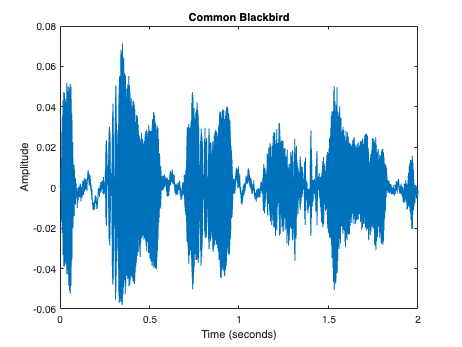

plot((0:numel(cb)-1)/cbFs,cb)
title('Common Blackbird')
xlabel('Time (seconds)')
ylabel('Amplitude')

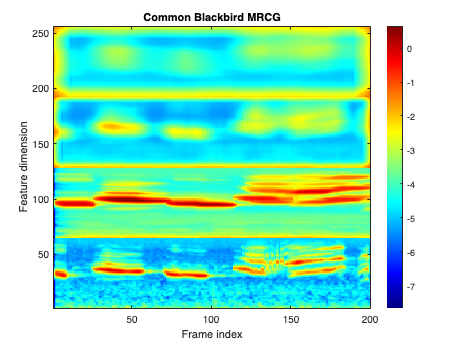

cbAudioOut = gammaFiltBank(cb);
cbMrcgFeatures = mrcg(cbAudioOut, cbFs);
imagesc(cbMrcgFeatures);
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Common Blackbird MRCG')
set(gca,'YDir','normal')

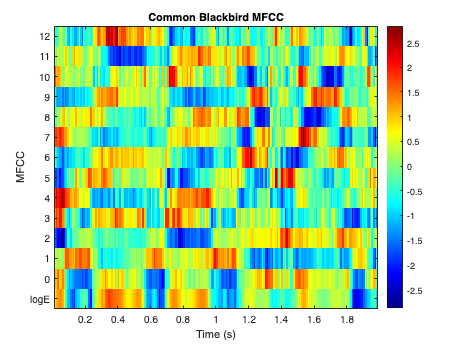

mfcc(cb, cbFs)
title('Common Blackbird MFCC')

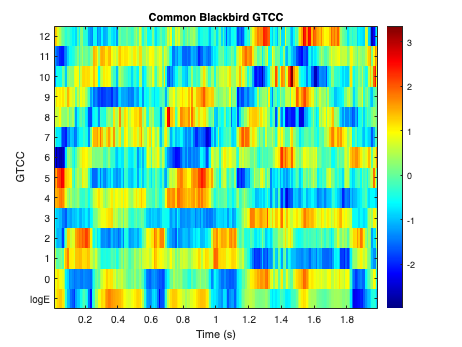

gtcc(cb, cbFs)
title('Common Blackbird GTCC')

**Long-tailed Tit features**

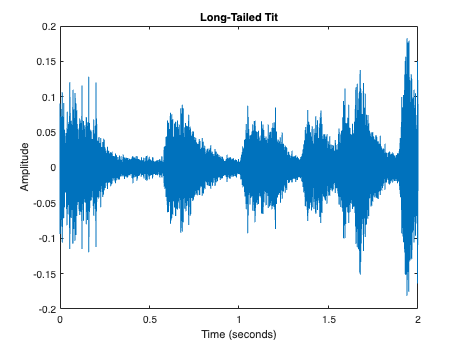

plot((0:numel(ltt)-1)/lttFs,ltt)
title('Long-Tailed Tit')
xlabel('Time (seconds)')
ylabel('Amplitude')

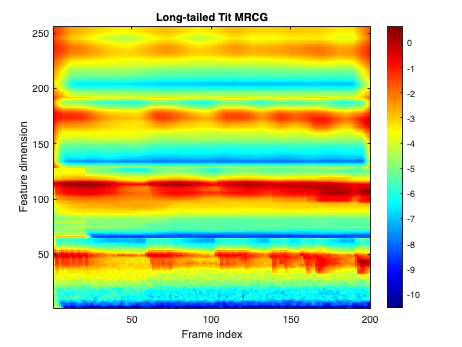

lttAudioOut = gammaFiltBank(ltt);
lttMrcgFeatures = mrcg(lttAudioOut, lttFs);
imagesc(lttMrcgFeatures);
colormap jet
colorbar
ylabel('Feature dimension')
xlabel('Frame index')
title('Long-tailed Tit MRCG')
set(gca,'YDir','normal')

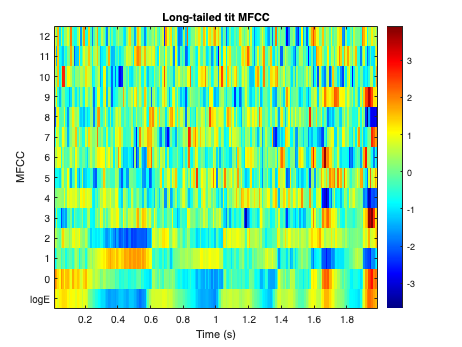

mfcc(ltt, lttFs)
title('Long-tailed tit MFCC')

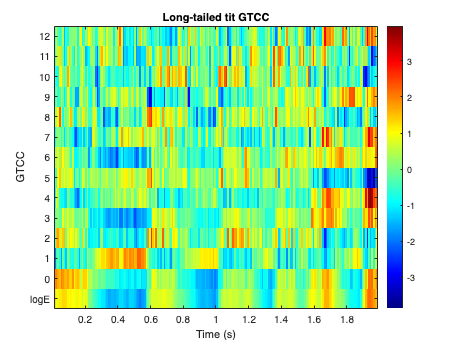

gtcc(ltt, lttFs)
title('Long-tailed tit GTCC')